Beginning of Project 1: Plotting Data


%%%%%%%% Connor McCarthy 
%%%%%%%% 8/24/21 
%%%%%%%% ME 4133 Machine Design 
%%%%%%%% Project 1: Plotting Data



%Begin Setup

D = ProjectIPlottingFall2020; %Set a variable equal to the table of data for ease of reference

%%%% Defining variables as column arrays of the table data for easy
%%%% reference during plotting

theta2 = D{:,1} ;
theta3 = D{:,2} ;
R3 = D{:,3} ;
R4 = D{:,4} ;
R5 = D{:,5} ;
h3 = D{:,6} ;
f3 = D{:,7} ;
f4 = D{:,8} ;
f5 = D{:,9} ;
h3p = D{:,10} ;
f3p = D{:,11} ;
f4p = D{:,12} ;
f5p = D{:,13} ;
%%%%%%%%%%%%%%%%%%


Plot 1: Position Analysis


%   Defining local mins and maxs


R3min = islocalmin(R3); %%%%Finding local mins and maxes found here: https://www.mathworks.com/help/matlab/ref/islocalmin.html

R3min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


R4min = islocalmin(R4);

R4min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


R5min = islocalmin(R5);

R5min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


T3min = islocalmin(theta3);

T3min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0




R3max = islocalmax(R3);

R3max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


R4max = islocalmax(R4);

R4max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


R5max = islocalmax(R5);

R5max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


T3max = islocalmax(theta3);

T3max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


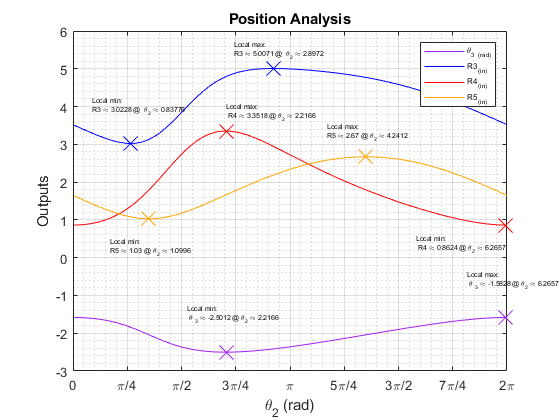



%%%%%%%%%%% Plotting the Outputs %%%%%%%%%%%%%


figure

plot(theta2,theta3 , "Color", "#A020F0")
hold on
plot(theta2,R3 , "Color", "blue") %%%% Hold on hold off learned from here: https://www.mathworks.com/matlabcentral/answers/292226-how-to-plot-multiple-lines-in-a-graph

plot(theta2,R4 , "Color"', "red" )

plot(theta2,R5 , "Color"', "#FFA500")





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%        Plotting the local mins and maxs   with labels    %

plot(theta2(R3min),R3(R3min),'X', 'MarkerSize',15, "Color", "blue"); %%%%Marker Size Syntax learned from here: https://www.mathworks.com/matlabcentral/answers/6537-how-do-i-change-the-marker-size-for-a-plot
text(theta2(R3min)-.56,R3(R3min)+1,sprintf(['Local min:' '\nR3 \\approx ' num2str(R3(R3min)) ' @  \\theta_{2} \\approx ' num2str(theta2(R3min))]), 'FontSize',5) %%%% Printing text at local min
%
plot(theta2(R4min),R4(R4min),'X', 'MarkerSize',15, "Color", "red");
text(theta2(R4min)-1.3,R4(R4min)-.5,sprintf(['Local min:' '\n R4 \\approx ' num2str(R4(R4min)) ' @ \\theta_{2} \\approx ' num2str(theta2(R4min))]), 'FontSize',5)
%
plot(theta2(R5min),R5(R5min),'X', 'MarkerSize',15, "Color", "#FFA500");
text(theta2(R5min)-.56,R5(R5min)-.75,sprintf(['Local min:' '\nR5 \\approx ' num2str(R5(R5min)) ' @ \\theta_{2} \\approx ' num2str(theta2(R5min))]), 'FontSize',5)
%
plot(theta2(T3min),theta3(T3min),'X', 'MarkerSize',15, "Color", "#A020F0");
text(theta2(T3min)-.56,theta3(T3min)+1,sprintf(['Local min:' '\n \\theta _{3} \\approx ' num2str(theta3(T3min)) ' @ \\theta_{2} \\approx ' num2str(theta2(T3min))]), 'FontSize',5)


plot(theta2(R3max),R3(R3max),'X', 'MarkerSize',15, "Color", "blue"); %%%%Marker Size Syntax learned from here: https://www.mathworks.com/matlabcentral/answers/6537-how-do-i-change-the-marker-size-for-a-plot
text(theta2(R3max)-.56,R3(R3max)+.5,sprintf(['Local max:' '\nR3 \\approx ' num2str(R3(R3max)) ' @  \\theta_{2} \\approx ' num2str(theta2(R3max))]), 'FontSize',5) %%%% Printing text at local min
%
plot(theta2(R4max),R4(R4max),'X', 'MarkerSize',15, "Color", "red");
text(theta2(R4max),R4(R4max)+.5,sprintf(['Local max:' '\n R4 \\approx ' num2str(R4(R4max)) ' @ \\theta_{2} \\approx ' num2str(theta2(R4max))]), 'FontSize',5)
%
plot(theta2(R5max),R5(R5max),'X', 'MarkerSize',15, "Color", "#FFA500" );
text(theta2(R5max)-.56,R5(R5max)+.65,sprintf(['Local max:' '\nR5 \\approx ' num2str(R5(R5max)) ' @ \\theta_{2} \\approx ' num2str(theta2(R5max))]), 'FontSize',5)
%
plot(theta2(T3max),theta3(T3max),'X', 'MarkerSize',15, "Color", "#A020F0");
text(theta2(T3max)-.56,theta3(T3max)+1,sprintf(['Local max:' '\n \\theta _{3} \\approx ' num2str(theta3(T3max)) ' @ \\theta_{2} \\approx ' num2str(theta2(T3max))]), 'FontSize',5)





%%% Configuring the data and axis display settings

grid on                %%% Grid Syntax learned from here: https://www.mathworks.com/help/matlab/ref/grid.html
grid minor
title('Position Analysis') %%%General plotting learned from here: https://www.mathworks.com/matlabcentral/answers/223794-plotting-data-from-a-table
xlabel('\theta_2 (rad)')
ylabel('Outputs')
xticks([0 .25*pi .5*pi .75*pi pi 1.25*pi 1.5*pi 1.75*pi 2*pi]) %%% Setting X ticks and X ticks labels found here: https://www.mathworks.com/help/matlab/creating_plots/change-tick-marks-and-tick-labels-of-graph-1.html
xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'})
xlim([0,(2*pi)])
ylim([-3,6])
legend('\theta_3 _{(rad)}','R3_{(in)}','R4_{(in)}','R5_{(in)}','FontSize',6)

Plot 2: 1st Order Kinematic Coefficients 

%Set up the figure, plot the variables against theta 2

figure
plot(theta2,h3 , "Color", "#A020F0") %%%% Hold on hold off learned from here: https://www.mathworks.com/matlabcentral/answers/292226-how-to-plot-multiple-lines-in-a-graph
hold on
plot(theta2,f3 , "Color", "blue")
%hold on 
plot(theta2,f4, "Color"', "red")
%hold on
plot(theta2,f5, "Color"', "#FFA500")
%hold on 

%   Defining local mins and maxs


f3min = islocalmin(f3); %%%%Finding local mins and maxes found here: https://www.mathworks.com/help/matlab/ref/islocalmin.html

f3min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


f4min = islocalmin(f4);

f4min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


f5min = islocalmin(f5);

f5min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


h3min = islocalmin(h3);

h3min = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0




f3max = islocalmax(f3);

f3max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


f4max = islocalmax(f4);

f4max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


f5max = islocalmax(f5);

f5max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


h3max = islocalmax(h3);

h3max = 361×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


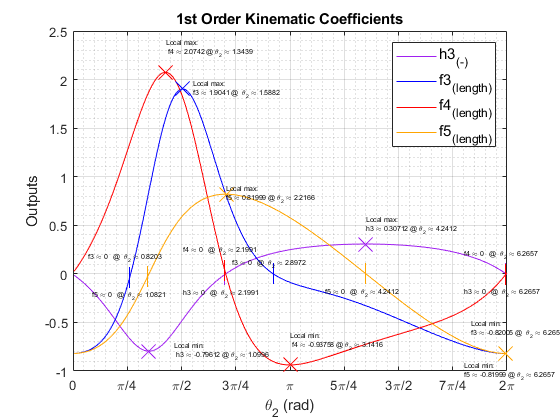


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%        Plotting the local mins and maxs   with labels    %

plot(theta2(f3min),f3(f3min),'X', 'MarkerSize',15, "Color", "blue"); %%%%Marker Size Syntax learned from here: https://www.mathworks.com/matlabcentral/answers/6537-how-do-i-change-the-marker-size-for-a-plot
text(theta2(f3min)-.5,f3(f3min)+.25,sprintf(['Local min:' '\nf3 \\approx ' num2str(f3(f3min)) ' @  \\theta_{2} \\approx ' num2str(theta2(f3min))]), 'FontSize',5) %%%% Printing text at local min
%
plot(theta2(f4min),f4(f4min),'X', 'MarkerSize',15, "Color", "red");
text(theta2(f4min),f4(f4min)+.25,sprintf(['Local min:' '\n f4 \\approx ' num2str(f4(f4min)) ' @ \\theta_{2} \\approx ' num2str(theta2(f4min))]), 'FontSize',5)
%
plot(theta2(f5min),f5(f5min),'X', 'MarkerSize',15, "Color", "#FFA500");
text(theta2(f5min)-.6,f5(f5min)-.18,sprintf(['Local min:' '\nf5 \\approx ' num2str(f5(f5min)) ' @ \\theta_{2} \\approx ' num2str(theta2(f5min))]), 'FontSize',5)
%
plot(theta2(h3min),h3(h3min),'X', 'MarkerSize',15, "Color", "#A020F0");
text(theta2(h3min)+.36,h3(h3min),sprintf(['Local min:' '\n h3 \\approx ' num2str(h3(h3min)) ' @ \\theta_{2} \\approx ' num2str(theta2(h3min))]), 'FontSize',5)


plot(theta2(f3max),f3(f3max),'X', 'MarkerSize',15, "Color", "blue"); %%%%Marker Size Syntax learned from here: https://www.mathworks.com/matlabcentral/answers/6537-how-do-i-change-the-marker-size-for-a-plot
text(theta2(f3max)+.15,f3(f3max),sprintf(['Local max:' '\nf3 \\approx ' num2str(f3(f3max)) ' @  \\theta_{2} \\approx ' num2str(theta2(f3max))]), 'FontSize',5) %%%% Printing text at local min
%
plot(theta2(f4max),f4(f4max),'X', 'MarkerSize',15, "Color", "red");
text(theta2(f4max),f4(f4max)+.25,sprintf(['Local max:' '\n f4 \\approx ' num2str(f4(f4max)) ' @ \\theta_{2} \\approx ' num2str(theta2(f4max))]), 'FontSize',5)
%
plot(theta2(f5max),f5(f5max),'X', 'MarkerSize',15, "Color", "#FFA500" );
text(theta2(f5max),f5(f5max),sprintf(['Local max:' '\nf5 \\approx ' num2str(f5(f5max)) ' @ \\theta_{2} \\approx ' num2str(theta2(f5max))]), 'FontSize',5)
%
plot(theta2(h3max),h3(h3max),'X', 'MarkerSize',15, "Color", "#A020F0");
text(theta2(h3max),h3(h3max)+.2,sprintf(['Local max:' '\nh3 \\approx ' num2str(h3(h3max)) ' @ \\theta_{2} \\approx ' num2str(theta2(h3max))]), 'FontSize',5)


%%%%%% Lets define some variables as the zeroes of our functions. This is
%%%%%% going to find the places in the data where the sign changes from
%%%%%% one cell to the next.

h3zeroes = find(h3(:).*circshift(h3(:), [-1 0]) <= 0 ) ;    %Using Circshift learned here https://www.mathworks.com/matlabcentral/answers/267222-easy-way-of-finding-zero-crossing-of-a-function
f3zeroes = find(f3(:).*circshift(f3(:), [-1 0]) <= 0 ) ;
f4zeroes = find(f4(:).*circshift(f4(:), [-1 0]) <= 0 ) ;    % Note; This will give you the index of the cell containing the y-value right before it crosses the x-axis. Nowhere in the data is
f5zeroes = find(f5(:).*circshift(f5(:), [-1 0]) <= 0 ) ;    % the function actually equal to zero. Using this data from the cell is an APPROXIMATE zero. This can be verified in the data table to be ~.01 off of zero

%%% Note 2 about circshift method; This method was gathered from an online
%%% resource, which requires validation to ensure it is working properly. I
%%% validated this technique by comparing the values it spit out to the raw
%%% data. When corss-referencing the raw data, it returns the index of the
%%% cell prvious to the sign change. Therefore, if row one has a negative
%%% value and row two has a positive value, this code detects the sign
%%% change and returns the index of row 1. After displaying this, I checked
%%% these indexes in the raw data and found that they were accurate. 



%%%%%% Plotting all the zeroes, markers and text boxes
plot(theta2(h3zeroes,1),h3(h3zeroes,1),'|', 'MarkerSize',15, "Color", "#A020F0")
text(theta2(h3zeroes(1,1),1)-.6,h3(h3zeroes(1,1),1)-.2,sprintf(['h3 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(h3zeroes(1,1),1))]), 'FontSize',5)
text(theta2(h3zeroes(2,1),1)-.6,h3(h3zeroes(2,1),1)-.2,sprintf(['h3 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(h3zeroes(2,1),1))]), 'FontSize',5)

plot(theta2(f3zeroes,1),f3(f3zeroes,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(f3zeroes(1,1),1)-.6,f3(f3zeroes(1,1),1)+.2,sprintf(['f3 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f3zeroes(1,1),1))]), 'FontSize',5)
text(theta2(f3zeroes(2,1),1)-.6,f3(f3zeroes(2,1),1)+.1,sprintf(['f3 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f3zeroes(2,1),1))]), 'FontSize',5)

plot(theta2(f4zeroes,1),f4(f4zeroes,1),'|', 'MarkerSize',15, "Color", "red")
text(theta2(f4zeroes(1,1),1)-.6,f4(f4zeroes(1,1),1)+.2,sprintf(['f4 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f4zeroes(1,1),1))]), 'FontSize',5)
text(theta2(f4zeroes(2,1),1)-.6,f4(f4zeroes(2,1),1)+.2,sprintf(['f4 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f4zeroes(2,1),1))]), 'FontSize',5)

plot(theta2(f5zeroes,1),f5(f5zeroes,1),'|', 'MarkerSize',15, "Color", "#FFA500")
text(theta2(f5zeroes(1,1),1)-.8,f5(f5zeroes(1,1),1)-.2,sprintf(['f5 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f5zeroes(1,1),1))]), 'FontSize',5)
text(theta2(f5zeroes(2,1),1)-.6,f5(f5zeroes(2,1),1)-.2,sprintf(['f5 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f5zeroes(2,1),1))]), 'FontSize',5)






%%% Configuring the data and axis display settings

grid on                %%% Grid Syntax learned from here: https://www.mathworks.com/help/matlab/ref/grid.html
grid minor
title('1st Order Kinematic Coefficients') %%%General plotting figured out here: https://www.mathworks.com/matlabcentral/answers/223794-plotting-data-from-a-table
xlabel('\theta_2 (rad)')
ylabel('Outputs')
xticks([0 .25*pi .5*pi .75*pi pi 1.25*pi 1.5*pi 1.75*pi 2*pi]) %%% Setting X ticks and X ticks labels found here: https://www.mathworks.com/help/matlab/creating_plots/change-tick-marks-and-tick-labels-of-graph-1.html
xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'})
xlim([0,(2*pi)])
ylim([-1,2.5])
legend('h3_{(-)}','f3_{(length)}','f4_{(length)}','f5_{(length)}','FontSize',11)

Plot 3: 2nd Order Kinematic Coefficients

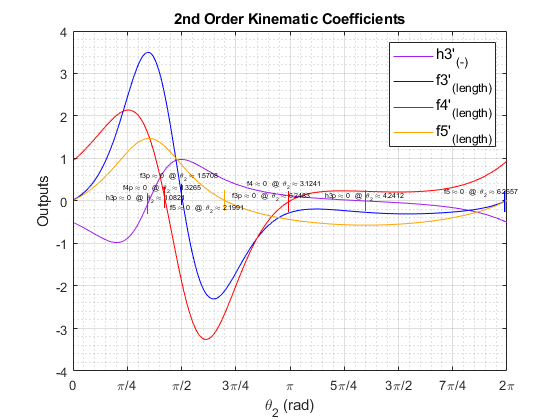

%Set up the figure, plot the variables against theta 2

figure
plot(theta2,h3p, "Color", "#A020F0") %%%% Hold on hold off learned from here: https://www.mathworks.com/matlabcentral/answers/292226-how-to-plot-multiple-lines-in-a-graph
hold on
plot(theta2,f3p, "Color", "blue") 
plot(theta2,f4p, "Color"', "red")
plot(theta2,f5p, "Color"', "#FFA500")


%%%%Find Zeros
h3pzeroes = find(h3p(:).*circshift(h3p(:), [-1 0]) <= 0 ) ;    %Using Circshift learned here https://www.mathworks.com/matlabcentral/answers/267222-easy-way-of-finding-zero-crossing-of-a-function
f3pzeroes = find(f3p(:).*circshift(f3p(:), [-1 0]) <= 0 ) ;
f4pzeroes = find(f4p(:).*circshift(f4p(:), [-1 0]) <= 0 ) ;    % Note; This will give you the index of the cell containing the y-value right before it crosses the x-axis. Nowhere in the data is
f5pzeroes = find(f5p(:).*circshift(f5p(:), [-1 0]) <= 0 ) ;    % the function actually equal to zero. Using this data from the cell is an APPROXIMATE zero. This can be verified in the data table to be ~.01 off of zero


%%%%%% Plotting all the zeroes, markers and text boxes
plot(theta2(h3pzeroes,1),h3p(h3pzeroes,1),'|', 'MarkerSize',15, "Color", "#A020F0")
text(theta2(h3pzeroes(1,1),1)-.6,h3p(h3pzeroes(1,1),1)+.1,sprintf(['h3p \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(h3pzeroes(1,1),1))]), 'FontSize',5)
text(theta2(h3pzeroes(2,1),1)-.6,h3p(h3pzeroes(2,1),1)+.1,sprintf(['h3p \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(h3pzeroes(2,1),1))]), 'FontSize',5)

plot(theta2(f3pzeroes,1),f3p(f3pzeroes,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(f3pzeroes(1,1),1)-.6,f3p(f3pzeroes(1,1),1)+.4,sprintf(['f3p \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f3pzeroes(1,1),1))]), 'FontSize',5)
text(theta2(f3zeroes(2,1),1)-.6,f3p(f3pzeroes(2,1),1)+.1,sprintf(['f3p \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f3pzeroes(2,1),1))]), 'FontSize',5)

plot(theta2(f4pzeroes,1),f4p(f4pzeroes,1),'|', 'MarkerSize',15, "Color", "red")
text(theta2(f4pzeroes(1,1),1)-.6,f4p(f4pzeroes(1,1),1)+.2,sprintf(['f4p \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f4pzeroes(1,1),1))]), 'FontSize',5)
text(theta2(f4pzeroes(2,1),1)-.6,f4p(f4pzeroes(2,1),1)+.4,sprintf(['f4 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f4pzeroes(2,1),1))]), 'FontSize',5)

plot(theta2(f5pzeroes,1),f5p(f5pzeroes,1),'|', 'MarkerSize',15, "Color", "#FFA500")
text(theta2(f5pzeroes(1,1),1)-.8,f5p(f5pzeroes(1,1),1)-.2,sprintf(['f5 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f5pzeroes(1,1),1))]), 'FontSize',5)
text(theta2(f5pzeroes(2,1),1)-.9,f5p(f5pzeroes(2,1),1)+.2,sprintf(['f5 \\approx ' num2str(0) '   @  \\theta_{2} \\approx ' num2str(theta2(f5pzeroes(2,1),1))]), 'FontSize',5)



%%% Configuring the data and axis display settings

grid on                %%% Grid Syntax learned from here: https://www.mathworks.com/help/matlab/ref/grid.html
grid minor
title('2nd Order Kinematic Coefficients') %%%General plotting figured out here: https://www.mathworks.com/matlabcentral/answers/223794-plotting-data-from-a-table
xlabel('\theta_2 (rad)')
ylabel('Outputs')
xticks([0 .25*pi .5*pi .75*pi pi 1.25*pi 1.5*pi 1.75*pi 2*pi]) %%% Setting X ticks and X ticks labels found here: https://www.mathworks.com/help/matlab/creating_plots/change-tick-marks-and-tick-labels-of-graph-1.html
xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'})
xlim([0,(2*pi)])
ylim([-4,4])
legend('h3''_{(-)}','f3''_{(length)}','f4''_{(length)}','f5''_{(length)}','FontSize',11)

Plot 4: Checking plotting accuracy by randomly testing points on Plot 2

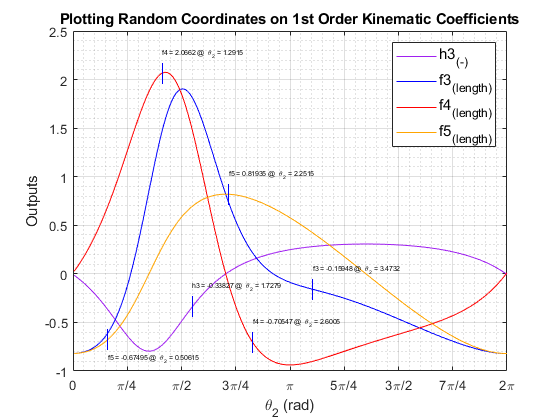

figure
plot(theta2,h3 , "Color", "#A020F0") %%%% Hold on hold off learned from here: https://www.mathworks.com/matlabcentral/answers/292226-how-to-plot-multiple-lines-in-a-graph
hold on
plot(theta2,f3 , "Color", "blue")
%hold on 
plot(theta2,f4, "Color"', "red")
%hold on
plot(theta2,f5, "Color"', "#FFA500")
%hold on 







%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% Validating Points Randomly On Plot
plot(theta2(100,1),h3(100,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(100,1),h3(100,1)+.2,sprintf(['h3 = ' num2str(h3(100,1)) ' @  \\theta_{2} = ' num2str(theta2(100,1))]), 'FontSize',5)

plot(theta2(200,1),f3(200,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(200,1),f3(200,1)+.2,sprintf(['f3 = ' num2str(f3(200,1)) ' @  \\theta_{2} = ' num2str(theta2(200,1))]), 'FontSize',5)

plot(theta2(75,1),f4(75,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(75,1),f4(75,1)+.2,sprintf(['f4 = ' num2str(f4(75,1)) ' @  \\theta_{2} = ' num2str(theta2(75,1))]), 'FontSize',5)

plot(theta2(150,1),f4(150,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(150,1),f4(150,1)+.2,sprintf(['f4 = ' num2str(f4(150,1)) ' @  \\theta_{2} = ' num2str(theta2(150,1))]), 'FontSize',5)

plot(theta2(30,1),f5(30,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(30,1),f5(30,1)-.2,sprintf(['f5 = ' num2str(f5(30,1)) ' @  \\theta_{2} = ' num2str(theta2(30,1))]), 'FontSize',5)

plot(theta2(130,1),f5(130,1),'|', 'MarkerSize',15, "Color", "blue")
text(theta2(130,1),f5(130,1)+.2,sprintf(['f5 = ' num2str(f5(130,1)) ' @  \\theta_{2} = ' num2str(theta2(130,1))]), 'FontSize',5)



%%% Configuring the data and axis display settings


grid on                %%% Grid Syntax learned from here: https://www.mathworks.com/help/matlab/ref/grid.html
grid minor
title('Plotting Random Coordinates on 1st Order Kinematic Coefficients') %%%General plotting figured out here: https://www.mathworks.com/matlabcentral/answers/223794-plotting-data-from-a-table
xlabel('\theta_2 (rad)')
ylabel('Outputs')
xticks([0 .25*pi .5*pi .75*pi pi 1.25*pi 1.5*pi 1.75*pi 2*pi]) %%% Setting X ticks and X ticks labels found here: https://www.mathworks.com/help/matlab/creating_plots/change-tick-marks-and-tick-labels-of-graph-1.html
xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'})
xlim([0,(2*pi)])
ylim([-1,2.5])
legend('h3_{(-)}','f3_{(length)}','f4_{(length)}','f5_{(length)}','FontSize',11)







disp(D);

    theta2rad    theta3rad     R3in      R4in       R5in         h3           f3in          f4in          f5in          h3p          f3pin        f4pin        f5pin  
    _________    _________    ______    _______    ______    __________    __________    __________    __________    __________    _________    _________    _________

         NaN          NaN        NaN        NaN       NaN           NaN           NaN           NaN           NaN           NaN          NaN          NaN          NaN
    0.017453       -1.583      3.506     0.8628    1.634